**1 a) OPEN ANALYSIS**

num = [100]

num = 100

den = [1 15 50]

den =      1    15    50


g = tf (num  , den )


g =
 
        100
  ---------------
  s^2 + 15 s + 50
 
Continuous-time transfer function.


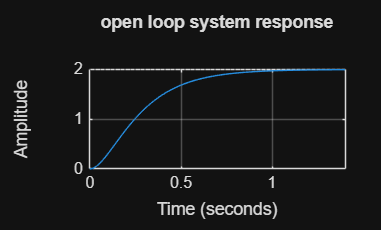

step (g)
grid on 
title ('open loop system response')

stepinfo (g)

ans = struct with fields:
         RiseTime: 0.5180
    TransientTime: 0.9200
     SettlingTime: 0.9200
      SettlingMin: 1.8045
      SettlingMax: 1.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9983
         PeakTime: 1.5565


ess = abs (1-dcgain(g))

ess = 1

**b) P CONTROLLER DESIGN **

p_controller = tf (0.5 , 1)


p_controller =
 
  0.5
 
Static gain.


closed_loop_step_resposne_p = feedback(p_controller*g,1)


closed_loop_step_resposne_p =
 
         50
  ----------------
  s^2 + 15 s + 100
 
Continuous-time transfer function.


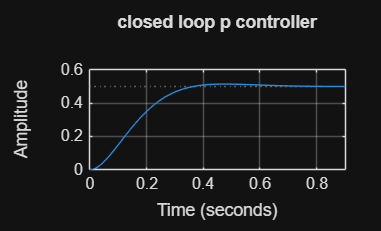

step (closed_loop_step_resposne_p)
grid on 
title ('closed loop p controller')

stepinfo (closed_loop_step_resposne_p)

ans = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728


ess_p_ccontroller = abs(1-dcgain(closed_loop_step_resposne_p)) 

ess_p_ccontroller = 0.5000

**c) PI CONTROLLER DESIGN**

integral action summed up ther error existiong over time to reach the required output which kind of was stagnant if only the propoertioanlity was there .

p_i_controller = pid(0.5,1.5,0)


p_i_controller =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.5, Ki = 1.5
 
Continuous-time PI controller in parallel form.


closed_loop_step_response_p_i = feedback(p_i_controller*g,1)


closed_loop_step_response_p_i =
 
          50 s + 150
  --------------------------
  s^3 + 15 s^2 + 100 s + 150
 
Continuous-time transfer function.


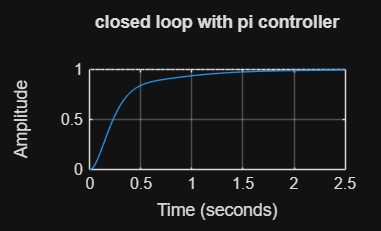

step (closed_loop_step_response_p_i)
grid on 
title ('closed loop with pi controller')

stepinfo(closed_loop_step_response_p_i)

ans = struct with fields:
         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861


ess_p_i_controller = abs(1-dcgain(closed_loop_step_response_p_i))

ess_p_i_controller = 0

**d) PID CONTROL TUNING **

kp = 0.5 , ki = 1.5 , kd = 0.1 , at first cahnged pd tp 1 then on keeping it reducing i got these values satisfying the required value by hit and trial .

p_i_d_controller = pid(0.5,1.5,0.1)


p_i_d_controller =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.5, Ki = 1.5, Kd = 0.1
 
Continuous-time PID controller in parallel form.


closed_loop_step_response_p_i_d= feedback(p_i_d_controller*g,1)


closed_loop_step_response_p_i_d =
 
     10 s^2 + 50 s + 150
  --------------------------
  s^3 + 25 s^2 + 100 s + 150
 
Continuous-time transfer function.


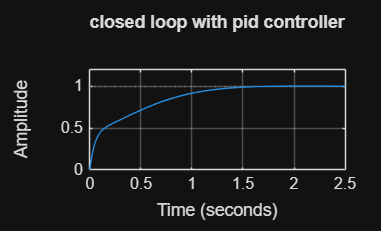

step (closed_loop_step_response_p_i_d)
grid on 
title ('closed loop with pid controller')

stepinfo(closed_loop_step_response_p_i_d)

ans = struct with fields:
         RiseTime: 0.9216
    TransientTime: 1.3659
     SettlingTime: 1.3659
      SettlingMin: 0.9008
      SettlingMax: 1.0043
        Overshoot: 0.4285
       Undershoot: 0
             Peak: 1.0043
         PeakTime: 2.1009


ess_p_i_controller = abs(1-dcgain(closed_loop_step_response_p_i_d))

ess_p_i_controller = 0

**2 a) MUTLI STEP RESPONSE **

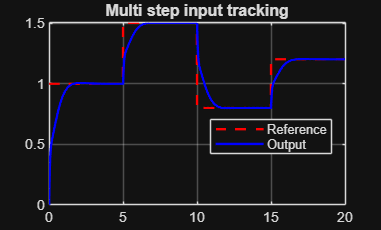

t = 0:0.01:20;
r = zeros(size(t));
r(t>=0 & t<5) = 1;
r(t>=5 & t<10) = 1.5;
r(t>=10 & t<15) = 0.8;
r(t>=15) = 1.2;
[y,x] = lsim(closed_loop_step_response_p_i_d, r, t);
figure
plot(t, r, 'r--', x, y, 'b', 'LineWidth', 1.5);
legend('Reference', 'Output');
legend ('Location','Best');
grid on;
title('Multi step input tracking');

error = r - y

error =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093    0.9093 

**b) RAMP INPUT**

a pid can reduce the error for a ramp input but can never eliminate it .

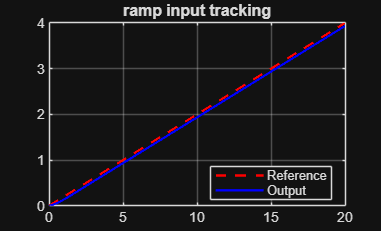

t=0:0.01:20;
r = 0.2*t;
[y,x] = lsim(closed_loop_step_response_p_i_d, r, t);
figure;
plot (t, r, 'r--', x, y, 'b', 'LineWidth', 1.5);
legend('Reference', 'Output');
legend ('Location','Best');
grid on;
title('ramp input tracking');

error = r - y

error =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980
   -0.0001    0.0019    0.0039    0.0059    0.0079    0.0099    0.0119    0.0139    0.0159    0.0179    0.0199    0.0219    0.0239    0.0259    0.0279    0.0299    0.0319    0.0339    0.0359    0.0379    0.0399    0.0419    0.0439    0.0459    0.0479    0.0499    0.0519    0.0539    0.0559    0.0579    0.0599    0.0619    0.0639    0.0659    0.0679    0.0699    0.0719    0.0739    0.0759    0.0779    0.0799    0.0819    0.0839    0.0859    0.0879    0.0899    0.0919    0.0939    0.0959 

**c) SINUSOIDAL INPUT **

derivative function add the most impact to the change in sinusoidal input as it adds to the phase lag .

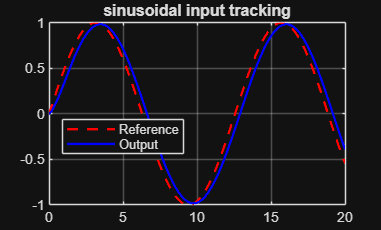

t= 0:0.01:20;
r = sin(0.5*t);
[y,x] = lsim(closed_loop_step_response_p_i_d, r, t);
figure;
plot (t, r, 'r--', x, y, 'b', 'LineWidth', 1.5);
legend('Reference', 'Output');
legend ('Location','Best');
grid on;
title('sinusoidal input tracking')

idx = t > 10;        

r_ss = r(idx);
y_ss = y(idx);
t_ss = t(idx);

[~, loc_r] = findpeaks(r_ss);
[~, loc_y] = findpeaks(y_ss);

t_r_peak = t_ss(loc_r(1));
t_y_peak = t_ss(loc_y(1));

time_delay = t_y_peak - t_r_peak;
omega = 0.5;

phase_lag_rad = omega * time_delay;
phase_lag_deg = phase_lag_rad * (180/pi);

fprintf('Phase lag = %.4f rad (%.2f degrees)\n', ...
        phase_lag_rad, phase_lag_deg);

**3) a) observing wind ups **

saturation occurs when the input provided by the controller reaches the capacity of plant to take as input .

the integral term without wind up keeps on increasing even though the plant is ressponding to the maximum but the error accumulation keeps on increasing .

when output finally reaches set point the integrator term starts decreasing from the point it has been increased to not from the max limit , leading into huge overshoot and settling time .

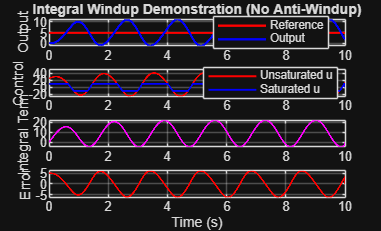

num = 50;
den = [1 8 25 20];         
G = tf(num, den);

Kp = 5;
Ki = 8;

dt = 0.001;                
T  = 10;                   
t  = 0:dt:T;
N  = length(t);
r = 5 * ones(1, N);
[A, B, C] = ssdata(G);

x = zeros(size(A,1), 1);  

integral_error = 0;

y_no  = zeros(1, N);
u       = zeros(1, N);    
u_sat   = zeros(1, N);    
e       = zeros(1, N);
I_term  = zeros(1, N);

u_max = 10;
u_min = -10;
for k = 1:N-1
    y_no(k) = C*x;
    e(k) = r(k) - y_no(k);
    integral_error = integral_error + e(k)*dt;
    u(k) = Kp*e(k) + Ki*integral_error;
    u_sat(k) = max(min(u(k), u_max), u_min);
    I_term(k) = Ki * integral_error;
    x = x + dt*(A*x + B*u_sat(k));
end

y_no(end) = C*x;

figure;

subplot(4,1,1)
plot(t, r, 'r', t, y_no, 'b', 'LineWidth', 1.5)
grid on
ylabel('Output')
legend('Reference','Output')
legend ('Location', "best")
title('Integral Windup Demonstration (No Anti-Windup)')

subplot(4,1,2)
plot(t, u, 'r', t, u_sat, 'b', 'LineWidth', 1.2)
grid on
ylabel('Control')
legend('Unsaturated u','Saturated u')
legend ('Location', "best")

subplot(4,1,3)
plot(t, I_term, 'm', 'LineWidth', 1.2)
grid on
ylabel('Integral Term')

subplot(4,1,4)
plot(t, e, 'r', 'LineWidth', 1.2)
grid on
ylabel('Error')
xlabel('Time (s)')

b) anti wind up prevents it by shutting down the error accumulation when the input reaches the input limit of plant once and reopens it when the error changes sign to negative sign thus restarting its calculation from the same place , no over addition . 

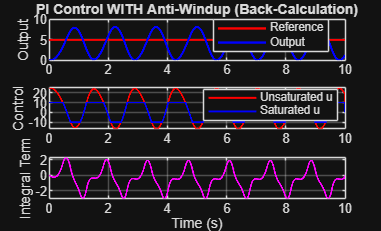

num = 50;
den = [1 8 25 20];
G = tf(num, den);
[A,B,C] = ssdata(G);

Kp = 5;
Ki = 8;
Kt = sqrt(Ki);         

dt = 0.001;
T  = 10;
t  = 0:dt:T;
N  = length(t);

r = 5 * ones(1, N);

u_max = 10;
u_min = -10;

x = zeros(size(A,1),1);    
integral_error = 0;

y_aw    = zeros(1,N);
e     = zeros(1,N);
u     = zeros(1,N);
u_sat = zeros(1,N);
Iterm = zeros(1,N);

for k = 1:N-1
    y_aw(k) = C*x;
    e(k) = r(k) - y_aw(k);
    u(k) = Kp*e(k) + Ki*integral_error;
    u_sat(k) = max(min(u(k), u_max), u_min);
    integral_error = integral_error + dt*( e(k) + (1/Kt)*(u_sat(k) - u(k)) );
    Iterm(k) = Ki * integral_error;
    x = x + dt*(A*x + B*u_sat(k));
end

y_aw(end) = C*x;
figure;

subplot(3,1,1)
plot(t, r, 'r', t, y_aw, 'b', 'LineWidth', 1.5)
grid on
ylabel('Output')
legend('Reference','Output')
legend ('Location','best')
title('PI Control WITH Anti-Windup (Back-Calculation)')

subplot(3,1,2)
plot(t, u, 'r', t, u_sat, 'b', 'LineWidth', 1.2)
grid on
ylabel('Control')
legend('Unsaturated u','Saturated u')
legend ('Location','best')

subplot(3,1,3)
plot(t, Iterm, 'm', 'LineWidth', 1.2)
grid on
ylabel('Integral Term')
xlabel('Time (s)')

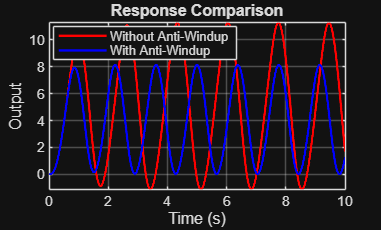


figure;
plot(t, y_no, 'r', t, y_aw, 'b', 'LineWidth', 1.5)
grid on
legend('Without Anti-Windup','With Anti-Windup')
legend ('Location', 'best')
title('Response Comparison')
xlabel('Time (s)')
ylabel('Output')

c ) while sensing the input from plant , some unwanted noise might be there in the input to controlller and whese high frequency noise undergoes the derivative operation , it leads to amplification , which might cause an impact on the input to the plant . so using a low pass filter helps us atteunate those unwanted high frequnecy waves . 

num = 50;
den = [1 8 25 20];
G = tf(num, den);
[A,B,C] = ssdata(G);

Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);             

dt = 0.001;
T  = 10;
t  = 0:dt:T;
N  = length(t);

r = 5 * ones(1,N);          

u_max = 10;               
u_min = -10;

noise_std = 0.05;           

wc = 7;                    
alpha = exp(-wc*dt);

x1 = zeros(size(A,1),1);   
x2 = zeros(size(A,1),1);   

I1 = 0; I2 = 0;

y1 = zeros(1,N); y2 = zeros(1,N);
u1 = zeros(1,N); u2 = zeros(1,N);
u1s = zeros(1,N); u2s = zeros(1,N);
e1 = zeros(1,N); e2 = zeros(1,N);

e_prev = 0;
ef = 0; ef_prev = 0;

for k = 1:N-1

    y1(k) = C*x1;
    yN1 = y1(k) + noise_std*randn;

    e1(k) = r(k) - yN1;
    de1 = (e1(k) - e_prev)/dt;

    u1(k) = Kp*e1(k) + Ki*I1 + Kd*de1;
    u1s(k) = max(min(u1(k),u_max),u_min);

    I1 = I1 + dt*( e1(k) + (1/Kt)*(u1s(k) - u1(k)) );

    x1 = x1 + dt*(A*x1 + B*u1s(k));

    y2(k) = C*x2;
    yN2 = y2(k) + noise_std*randn;

    e2(k) = r(k) - yN2;

    ef = alpha*ef + (1-alpha)*e2(k);
    de2 = (ef - ef_prev)/dt;

    u2(k) = Kp*e2(k) + Ki*I2 + Kd*de2;
    u2s(k) = max(min(u2(k),u_max),u_min);

    I2 = I2 + dt*( e2(k) + (1/Kt)*(u2s(k) - u2(k)) );

    x2 = x2 + dt*(A*x2 + B*u2s(k));

    e_prev = e1(k);
    ef_prev = ef;
end

y1(end) = C*x1;
y2(end) = C*x2;

std_u_unfiltered = std(u1);
std_u_filtered   = std(u2);

fprintf('Std of control (no filter) : %.4f\n', std_u_unfiltered);

Std of control (no filter) : 174.0445


fprintf('Std of control (filtered)  : %.4f\n', std_u_filtered);

Std of control (filtered)  : 13.1483


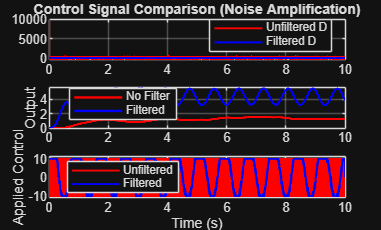


figure;

subplot(3,1,1)
plot(t,u1,'r',t,u2,'b','LineWidth',1.2)
grid on
legend('Unfiltered D','Filtered D')
legend ('Location','best')
title('Control Signal Comparison (Noise Amplification)')

subplot(3,1,2)
plot(t,y1,'r',t,y2,'b','LineWidth',1.5)
grid on
legend('No Filter','Filtered')
legend ('Location','best')
ylabel('Output')

subplot(3,1,3)
plot(t,u1s,'r',t,u2s,'b','LineWidth',1.2)
grid on
ylabel('Applied Control')
xlabel('Time (s)')
legend('Unfiltered','Filtered')
legend ('location','best')
ylim([-11 11])

d )The complete PID controller with derivative filtering and anti-windup successfully handles a mixed trajectory consisting of ramps, steps, and sinusoidal motion. Integral action ensures zero steady-state error for constant segments and enables ramp following with small residual error, derivative action improves sinusoidal tracking by reducing phase lag while filtered implementation avoids noise amplification, and proportional action provides immediate response. Anti-windup guarantees that actuator saturation does not cause integrator runaway, ensuring fast recovery and compliance with actuator limits throughout the trajectory.

num = 50;
den = [1 8 25 20];
G = tf(num, den);
[A,B,C,D] = ssdata(G);

Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);            

dt = 0.001;
T  = 20;
t  = 0:dt:T;
N  = length(t);

u_max = 10;
u_min = -10;

wc = 7;
alpha = exp(-wc*dt);

r = zeros(1,N);

for k = 1:N
    tk = t(k);

    if tk < 2
        r(k) = 0.5*tk;                          
    elseif tk < 4
        r(k) = 1;                              
    elseif tk < 8
        r(k) = 1 + 0.5*sin(2*pi*(tk-4));       
    elseif tk < 10
        r(k) = 2;                               
    elseif tk < 15
        r(k) = 2 - 0.3*(tk-10);                
    else
        r(k) = 0.5;                            

    end
end

x = zeros(size(A,1),1);
integral_error = 0;

y  = zeros(1,N);
e  = zeros(1,N);
u  = zeros(1,N);
u_sat = zeros(1,N);

e_filt = 0;
e_filt_prev = 0;

for k = 1:N-1

    y(k) = C*x;

    e(k) = r(k) - y(k);

    e_filt = alpha*e_filt + (1-alpha)*e(k);

    de = (e_filt - e_filt_prev)/dt;

    u(k) = Kp*e(k) + Ki*integral_error + Kd*de;

    u_sat(k) = max(min(u(k),u_max),u_min);

    integral_error = integral_error + ...
        dt*( e(k) + (1/Kt)*(u_sat(k) - u(k)) );

    x = x + dt*(A*x + B*u_sat(k));

    e_filt_prev = e_filt;
end

y(end) = C*x;

e_rms = sqrt(mean(e.^2));
fprintf('RMS tracking error: %.4f\n', e_rms);

RMS tracking error: 0.8596


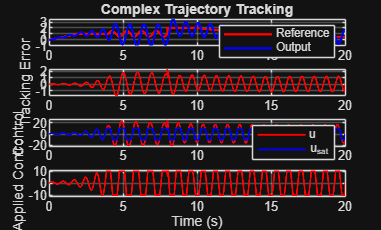


figure;

subplot(4,1,1)
plot(t,r,'r',t,y,'b','LineWidth',1.5)
grid on
legend('Reference','Output')
title('Complex Trajectory Tracking')

subplot(4,1,2)
plot(t,e,'r','LineWidth',1.2)
grid on
ylabel('Tracking Error')

subplot(4,1,3)
plot(t,u,'r',t,u_sat,'b','LineWidth',1.2)
grid on
ylabel('Control')
legend('u','u_{sat}')

subplot(4,1,4)
plot(t,u_sat,'r','LineWidth',1.2)
grid on
ylabel('Applied Control')
xlabel('Time (s)')
ylim([-11 11])